# S02S038OrbitAnalysis

Script for plotting and fitting orbit of start around the black hole in the center of the Milky Way.

Data from 

*AN IMPROVED DISTANCE AND MASS ESTIMATE FOR SGR A* FROM A MULTISTAR ORBIT ANALYSIS,*A. Boehle1, A. M. Ghez1, R. Schödel2, L. Meyer1, S. Yelda1, S. Albers1, G. D. Martinez1, E. E. Becklin1, T. Do1, J. R. Lu3 [http://iopscience.iop.org/article/10.3847/0004-637X/830/1/17](http://iopscience.iop.org/article/10.3847/0004-637X/830/1/17) , Table 3 and Table 7.

Note: Data for S38 has non-importable rows which should be excluded

Uses fit_ellipse from [https://www.mathworks.com/matlabcentral/fileexchange/3215-fit_ellipse](https://www.mathworks.com/matlabcentral/fileexchange/3215-fit_ellipse) 

Author: Duncan Carlsmith

%% Import data from text file.
% Script for importing data from the following text file:
%
%    /Users/duncancarlsmith/Documents/MATLAB/GeneralRelativity/S02OrbitSagA.txt
%
% To extend the code to different selected data or a different text file,
% generate a function instead of a script.

% Auto-generated by MATLAB on 2018/09/16 11:37:38

%% Initialize variables.
filename = 'S02OrbitSagA.txt';
delimiter = '\t';
startRow = 5;

%% Format for each line of text:
%   column1: double (%f)
%	column2: double (%f)
%   column3: double (%f)
%	column4: double (%f)
%   column5: double (%f)
% For more information, see the TEXTSCAN documentation.
formatSpec = '%f%f%f%f%f%[^\n\r]';

%% Open the text file.
fileID = fopen(filename,'r');

%% Read columns of data according to the format.
% This call is based on the structure of the file used to generate this
% code. If an error occurs for a different file, try regenerating the code
% from the Import Tool.
%textscan(fileID, '%[^\n\r]', startRow-1, 'WhiteSpace', '', 'ReturnOnError', false, 'EndOfLine', '\r\n');
%dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'TextType', 'string', 'ReturnOnError', false);

%% Close the text file.
fclose(fileID);

%% Post processing for unimportable data.
% No unimportable data rules were applied during the import, so no post
% processing code is included. To generate code which works for
% unimportable data, select unimportable cells in a file and regenerate the
% script.

%% Allocate imported array to column variable names
Date2 = dataArray{:, 1};

Undefined variable dataArray.

DeltaRA2 = dataArray{:, 2};
DeltaDecl2 = dataArray{:, 3};
DeltaRAError2 = dataArray{:, 4};
DeltaDeclError2 = dataArray{:, 5};


%% Clear temporary variables
clearvars filename delimiter startRow formatSpec fileID dataArray ans;

Import data from s038


%% Import data from text file.
% Script for importing data from the following text file:
%
%    /Users/duncancarlsmith/Documents/MATLAB/GeneralRelativity/S38OrbitSagA.txt
%
% To extend the code to different selected data or a different text file,
% generate a function instead of a script.

% Auto-generated by MATLAB on 2018/09/16 12:08:48

%% Initialize variables.
filename = 'S38OrbitSagA.txt';
delimiter = '\t';
startRow = 7;
endRow = 41;

%% Read columns of data as text:
% For more information, see the TEXTSCAN documentation.
formatSpec = '%s%s%s%s%s%s%[^\n\r]';

%% Open the text file.
fileID = fopen(filename,'r');

%% Read columns of data according to the format.
% This call is based on the structure of the file used to generate this
% code. If an error occurs for a different file, try regenerating the code
% from the Import Tool.
textscan(fileID, '%[^\n\r]', startRow-1, 'WhiteSpace', '', 'ReturnOnError', false);
dataArray = textscan(fileID, formatSpec, endRow-startRow+1, 'Delimiter', delimiter, 'TextType', 'string', 'ReturnOnError', false, 'EndOfLine', '\r\n');

%% Close the text file.
fclose(fileID);

%% Convert the contents of columns containing numeric text to numbers.
% Replace non-numeric text with NaN.
raw = repmat({''},length(dataArray{1}),length(dataArray)-1);
for col=1:length(dataArray)-1
    raw(1:length(dataArray{col}),col) = mat2cell(dataArray{col}, ones(length(dataArray{col}), 1));
end
numericData = NaN(size(dataArray{1},1),size(dataArray,2));

for col=[1,2,3,4,5,6]
    % Converts text in the input cell array to numbers. Replaced non-numeric
    % text with NaN.
    rawData = dataArray{col};
    for row=1:size(rawData, 1)
        % Create a regular expression to detect and remove non-numeric prefixes and
        % suffixes.
        regexstr = '(?<prefix>.*?)(?<numbers>([-]*(\d+[\,]*)+[\.]{0,1}\d*[eEdD]{0,1}[-+]*\d*[i]{0,1})|([-]*(\d+[\,]*)*[\.]{1,1}\d+[eEdD]{0,1}[-+]*\d*[i]{0,1}))(?<suffix>.*)';
        try
            result = regexp(rawData(row), regexstr, 'names');
            numbers = result.numbers;
            
            % Detected commas in non-thousand locations.
            invalidThousandsSeparator = false;
            if numbers.contains(',')
                thousandsRegExp = '^\d+?(\,\d{3})*\.{0,1}\d*$';
                if isempty(regexp(numbers, thousandsRegExp, 'once'))
                    numbers = NaN;
                    invalidThousandsSeparator = true;
                end
            end
            % Convert numeric text to numbers.
            if ~invalidThousandsSeparator
                numbers = textscan(char(strrep(numbers, ',', '')), '%f');
                numericData(row, col) = numbers{1};
                raw{row, col} = numbers{1};
            end
        catch
            raw{row, col} = rawData{row};
        end
    end
end


%% Exclude rows with non-numeric cells
I = ~all(cellfun(@(x) (isnumeric(x) || islogical(x)) && ~isnan(x),raw),2); % Find rows with non-numeric cells
raw(I,:) = [];

%% Allocate imported array to column variable names
Date1 = cell2mat(raw(:, 1));
K = cell2mat(raw(:, 2));
DeltaRA1 = cell2mat(raw(:, 3));
DeltaDecl1 = cell2mat(raw(:, 4));
DeltaRAError1 = cell2mat(raw(:, 5));
DeltaDeclError1 = cell2mat(raw(:, 6));


%% Clear temporary variables
clearvars filename delimiter startRow endRow formatSpec fileID dataArray ans raw col numericData rawData row regexstr result numbers invalidThousandsSeparator thousandsRegExp I J;

### Plot orbit

fig=figure;
set(fig,'defaultLegendAutoUpdate','off')% prevent ellipse&line drawing from adding to legend 
errorbar(DeltaRA2,DeltaDecl2,-DeltaDeclError2,+DeltaDeclError2,...
    -DeltaRAError2,+DeltaRAError2,'.')

Unrecognized function or variable 'DeltaRA2'.

hold on
errorbar(DeltaRA1,DeltaDecl1,-DeltaDeclError1,+DeltaDeclError1,...
    -DeltaRAError1,+DeltaRAError1,'.')
xlabel('Right Ascension (arcsec)');ylabel('Declination (arcsec)')
title('Stellar orbits about SAGA*')



### Fit ellipses to orbits.

Note: This fit ignores the errors! Also, it fits for a tilted ellipse as a general conic section. See [https://en.wikipedia.org/wiki/Ellipse](https://en.wikipedia.org/wiki/Ellipse) 

axis_handle=gca;
ellipse_s0 = fit_ellipse( DeltaRA1,DeltaDecl1,axis_handle )

stopped because of a warning regarding matrix inversion

ellipse_s0 =

     []




ellipse_s38 = fit_ellipse( DeltaRA1,DeltaDecl1,axis_handle );

stopped because of a warning regarding matrix inversion


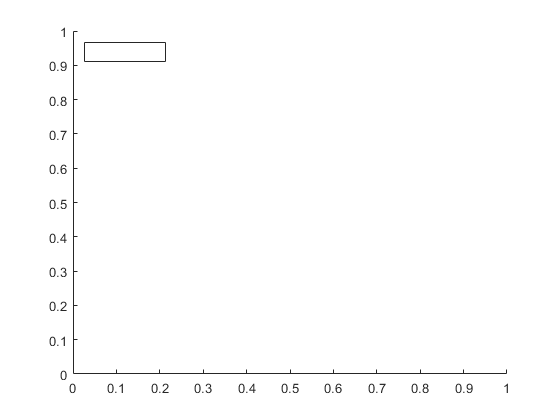

legend('S02','S38','Location','northwest')

function ellipse_t = fit_ellipse( x,y,axis_handle )
%
% fit_ellipse - finds the best fit to an ellipse for the given set of points.
%
% Format:   ellipse_t = fit_ellipse( x,y,axis_handle )
%
% Input:    x,y         - a set of points in 2 column vectors. AT LEAST 5 points are needed !
%           axis_handle - optional. a handle to an axis, at which the estimated ellipse 
%                         will be drawn along with it's axes
%
% Output:   ellipse_t - structure that defines the best fit to an ellipse
%                       a           - sub axis (radius) of the X axis of the non-tilt ellipse
%                       b           - sub axis (radius) of the Y axis of the non-tilt ellipse
%                       phi         - orientation in radians of the ellipse (tilt)
%                       X0          - center at the X axis of the non-tilt ellipse
%                       Y0          - center at the Y axis of the non-tilt ellipse
%                       X0_in       - center at the X axis of the tilted ellipse
%                       Y0_in       - center at the Y axis of the tilted ellipse
%                       long_axis   - size of the long axis of the ellipse
%                       short_axis  - size of the short axis of the ellipse
%                       status      - status of detection of an ellipse
%
% Note:     if an ellipse was not detected (but a parabola or hyperbola), then
%           an empty structure is returned

% =====================================================================================
%                  Ellipse Fit using Least Squares criterion
% =====================================================================================
% We will try to fit the best ellipse to the given measurements. the mathematical
% representation of use will be the CONIC Equation of the Ellipse which is:
% 
%    Ellipse = a*x^2 + b*x*y + c*y^2 + d*x + e*y + f = 0
%   
% The fit-estimation method of use is the Least Squares method (without any weights)
% The estimator is extracted from the following equations:
%
%    g(x,y;A) := a*x^2 + b*x*y + c*y^2 + d*x + e*y = f
%
%    where:
%       A   - is the vector of parameters to be estimated (a,b,c,d,e)
%       x,y - is a single measurement
%
% We will define the cost function to be:
%
%   Cost(A) := (g_c(x_c,y_c;A)-f_c)'*(g_c(x_c,y_c;A)-f_c)
%            = (X*A+f_c)'*(X*A+f_c) 
%            = A'*X'*X*A + 2*f_c'*X*A + N*f^2
%
%   where:
%       g_c(x_c,y_c;A) - vector function of ALL the measurements
%                        each element of g_c() is g(x,y;A)
%       X              - a matrix of the form: [x_c.^2, x_c.*y_c, y_c.^2, x_c, y_c ]
%       f_c            - is actually defined as ones(length(f),1)*f
%
% Derivation of the Cost function with respect to the vector of parameters "A" yields:
%
%   A'*X'*X = -f_c'*X = -f*ones(1,length(f_c))*X = -f*sum(X)
%
% Which yields the estimator:
%
%       ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
%       |  A_least_squares = -f*sum(X)/(X'*X) ->(normalize by -f) = sum(X)/(X'*X)  |
%       ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
%
% (We will normalize the variables by (-f) since "f" is unknown and can be accounted for later on)
%  
% NOW, all that is left to do is to extract the parameters from the Conic Equation.
% We will deal the vector A into the variables: (A,B,C,D,E) and assume F = -1;
%
%    Recall the conic representation of an ellipse:
% 
%       A*x^2 + B*x*y + C*y^2 + D*x + E*y + F = 0
% 
% We will check if the ellipse has a tilt (=orientation). The orientation is present
% if the coefficient of the term "x*y" is not zero. If so, we first need to remove the
% tilt of the ellipse.
%
% If the parameter "B" is not equal to zero, then we have an orientation (tilt) to the ellipse.
% we will remove the tilt of the ellipse so as to remain with a conic representation of an 
% ellipse without a tilt, for which the math is more simple:
%
% Non tilt conic rep.:  A`*x^2 + C`*y^2 + D`*x + E`*y + F` = 0
%
% We will remove the orientation using the following substitution:
%   
%   Replace x with cx+sy and y with -sx+cy such that the conic representation is:
%   
%   A(cx+sy)^2 + B(cx+sy)(-sx+cy) + C(-sx+cy)^2 + D(cx+sy) + E(-sx+cy) + F = 0
%
%   where:      c = cos(phi)    ,   s = sin(phi)
%
%   and simplify...
%
%       x^2(A*c^2 - Bcs + Cs^2) + xy(2A*cs +(c^2-s^2)B -2Ccs) + ...
%           y^2(As^2 + Bcs + Cc^2) + x(Dc-Es) + y(Ds+Ec) + F = 0
%
%   The orientation is easily found by the condition of (B_new=0) which results in:
% 
%   2A*cs +(c^2-s^2)B -2Ccs = 0  ==> phi = 1/2 * atan( b/(c-a) )
%   
%   Now the constants   c=cos(phi)  and  s=sin(phi)  can be found, and from them
%   all the other constants A`,C`,D`,E` can be found.
%
%   A` = A*c^2 - B*c*s + C*s^2                  D` = D*c-E*s
%   B` = 2*A*c*s +(c^2-s^2)*B -2*C*c*s = 0      E` = D*s+E*c 
%   C` = A*s^2 + B*c*s + C*c^2
%
% Next, we want the representation of the non-tilted ellipse to be as:
%
%       Ellipse = ( (X-X0)/a )^2 + ( (Y-Y0)/b )^2 = 1
%
%       where:  (X0,Y0) is the center of the ellipse
%               a,b     are the ellipse "radiuses" (or sub-axis)
%
% Using a square completion method we will define:
%       
%       F`` = -F` + (D`^2)/(4*A`) + (E`^2)/(4*C`)
%
%       Such that:    a`*(X-X0)^2 = A`(X^2 + X*D`/A` + (D`/(2*A`))^2 )
%                     c`*(Y-Y0)^2 = C`(Y^2 + Y*E`/C` + (E`/(2*C`))^2 )
%
%       which yields the transformations:
%       
%           X0  =   -D`/(2*A`)
%           Y0  =   -E`/(2*C`)
%           a   =   sqrt( abs( F``/A` ) )
%           b   =   sqrt( abs( F``/C` ) )
%
% And finally we can define the remaining parameters:
%
%   long_axis   = 2 * max( a,b )
%   short_axis  = 2 * min( a,b )
%   Orientation = phi
%
%

% initialize
orientation_tolerance = 1e-3;

% empty warning stack
warning( '' );

% prepare vectors, must be column vectors
x = x(:);
y = y(:);

% remove bias of the ellipse - to make matrix inversion more accurate. (will be added later on).
mean_x = mean(x);
mean_y = mean(y);
x = x-mean_x;
y = y-mean_y;

% the estimation for the conic equation of the ellipse
X = [x.^2, x.*y, y.^2, x, y ];
a = sum(X)/(X'*X);

% check for warnings
if ~isempty( lastwarn )
    disp( 'stopped because of a warning regarding matrix inversion' );
    ellipse_t = [];
    return
end

% extract parameters from the conic equation
[a,b,c,d,e] = deal( a(1),a(2),a(3),a(4),a(5) );

% remove the orientation from the ellipse
if ( min(abs(b/a),abs(b/c)) > orientation_tolerance )
    
    orientation_rad = 1/2 * atan( b/(c-a) );
    cos_phi = cos( orientation_rad );
    sin_phi = sin( orientation_rad );
    [a,b,c,d,e] = deal(...
        a*cos_phi^2 - b*cos_phi*sin_phi + c*sin_phi^2,...
        0,...
        a*sin_phi^2 + b*cos_phi*sin_phi + c*cos_phi^2,...
        d*cos_phi - e*sin_phi,...
        d*sin_phi + e*cos_phi );
    [mean_x,mean_y] = deal( ...
        cos_phi*mean_x - sin_phi*mean_y,...
        sin_phi*mean_x + cos_phi*mean_y );
else
    orientation_rad = 0;
    cos_phi = cos( orientation_rad );
    sin_phi = sin( orientation_rad );
end

% check if conic equation represents an ellipse
test = a*c;
switch (1)
case (test>0),  status = '';
case (test==0), status = 'Parabola found';  warning( 'fit_ellipse: Did not locate an ellipse' );
case (test<0),  status = 'Hyperbola found'; warning( 'fit_ellipse: Did not locate an ellipse' );
end

% if we found an ellipse return it's data
if (test>0)
    
    % make sure coefficients are positive as required
    if (a<0), [a,c,d,e] = deal( -a,-c,-d,-e ); end
    
    % final ellipse parameters
    X0          = mean_x - d/2/a;
    Y0          = mean_y - e/2/c;
    F           = 1 + (d^2)/(4*a) + (e^2)/(4*c);
    [a,b]       = deal( sqrt( F/a ),sqrt( F/c ) );    
    long_axis   = 2*max(a,b);
    short_axis  = 2*min(a,b);

    % rotate the axes backwards to find the center point of the original TILTED ellipse
    R           = [ cos_phi sin_phi; -sin_phi cos_phi ];
    P_in        = R * [X0;Y0];
    X0_in       = P_in(1);
    Y0_in       = P_in(2);
    
    % pack ellipse into a structure
    ellipse_t = struct( ...
        'a',a,...
        'b',b,...
        'phi',orientation_rad,...
        'X0',X0,...
        'Y0',Y0,...
        'X0_in',X0_in,...
        'Y0_in',Y0_in,...
        'long_axis',long_axis,...
        'short_axis',short_axis,...
        'status','' );
else
    % report an empty structure
    ellipse_t = struct( ...
        'a',[],...
        'b',[],...
        'phi',[],...
        'X0',[],...
        'Y0',[],...
        'X0_in',[],...
        'Y0_in',[],...
        'long_axis',[],...
        'short_axis',[],...
        'status',status );
end

% check if we need to plot an ellipse with it's axes.
if (nargin>2) & ~isempty( axis_handle ) & (test>0)
    
    % rotation matrix to rotate the axes with respect to an angle phi
    R = [ cos_phi sin_phi; -sin_phi cos_phi ];
    
    % the axes
    ver_line        = [ [X0 X0]; Y0+b*[-1 1] ];
    horz_line       = [ X0+a*[-1 1]; [Y0 Y0] ];
    new_ver_line    = R*ver_line;
    new_horz_line   = R*horz_line;
    
    % the ellipse
    theta_r         = linspace(0,2*pi);
    ellipse_x_r     = X0 + a*cos( theta_r );
    ellipse_y_r     = Y0 + b*sin( theta_r );
    rotated_ellipse = R * [ellipse_x_r;ellipse_y_r];
    
    % draw
    hold_state = get( axis_handle,'NextPlot' );
    set( axis_handle,'NextPlot','add' );
    plot( new_ver_line(1,:),new_ver_line(2,:),'r' );
    plot( new_horz_line(1,:),new_horz_line(2,:),'r' );
    plot( rotated_ellipse(1,:),rotated_ellipse(2,:),'r' );
    set( axis_handle,'NextPlot',hold_state );
end
end